# Documentation

This MATLAB LiveScript file demonstrates how to simulate wind speeds at a new set of points based on a given set of wind speed data at a  different set of points. The example uses a constrained wind simulation  technique, where the mean wind speed and turbulence intensity are  preserved at the new set of points. The script loads example wind speed  data and defines a new grid for the simulation. It then runs the  constrained wind simulation, visualizes the resulting wind speeds on the new grid, and compares the mean wind speeds, turbulence intensities,  and root-mean-square errors between the simulated and target wind  speeds. Finally, it compares the power spectral density and coherence of the simulated and target wind speeds.

## Load the data


clearvars;close all;clc;
load('exampleData.mat','u','t','nodes','v','w')

t = t(1:3:end);
u = u(1:3:end,:,:);
v = v(1:3:end,:,:);
w = w(1:3:end,:,:);
fs = 1./median(diff(t));
fprintf('Sampling frequency is %1.1f Hz \n',fs);

Sampling frequency is 3.0 Hz 



u0= u;
clear geometry
z = nodes.Z;
y = nodes.Y;

## Define a new grid


clf;close all;
rng(10)
Cuy = 7;  % Decay coeficient for Davenport model
Cuz = 7; % Decay coeficient for Davenport model

% reshape the data on the query points
N = numel(t);
u = reshape(u,N,[])';
y = y(:); 
z = z(:);

% New grid
[newY,newZ] = meshgrid(1.2*min(nodes.Y(:)):15:max(nodes.Y(:))*1.2,...
    0.9*min(nodes.Z(:)):15:1.1*max(nodes.Z(:)));
[Nyy,Nzz]=size(newY);
newY = newY(:);
newZ = newZ(:);

fprintf('The new grid is %i by %i \n',[Nyy,Nzz]);

The new grid is 12 by 13 


fprintf('The old grid is %i by %i \n',[size(nodes.Y,1),size(nodes.Y,2)]);

The old grid is 3 by 3 


% Remove nodes identical to the target nodes, if exist
for ii=1:numel(y)
    ind = find(newY(:)==y(ii) & newZ(:)==z(ii));
    if ~isempty(ind)
        newY(ind)=[];
        newZ(ind)=[];
    end
end

## Run the constrained wind simulation

tic
[newU,uCheck, nodes2] = condWindSim2D(u,t,y,z,newY,newZ,Cuy,Cuz);
toc

Elapsed time is 49.456285 seconds.



newU = reshape(newU,[],Nyy,Nzz);

## 2D visualization

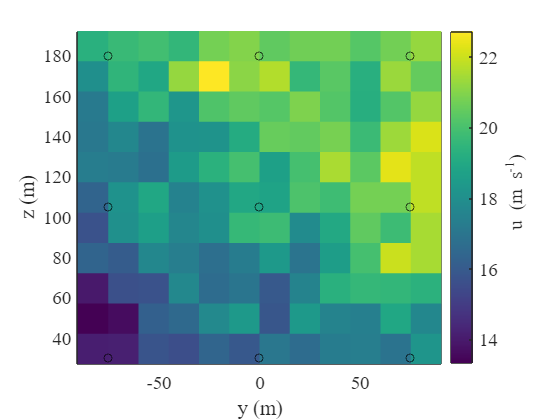

clf;close all;
figure
y1 = reshape(nodes2.Y,[size(squeeze(newU(10,:,:)))]);
z1 = reshape(nodes2.Z,[size(squeeze(newU(10,:,:)))]);
pcolor(y1,z1,squeeze(newU(1,:,:)));shading flat
hold on
plot(y,z,'ko')
axis equal
axis tight
set(gcf,'color','w');
c =colorbar;
ylabel(c,' u (m s^{-1})')
if exist('viridis','file'), colormap('viridis'); end;
set(findall(gcf,'-property','FontSize'),'FontSize',14,'FontName','Times')
set(gcf,'color','w')
ylabel('z (m)')
xlabel('y (m)')

## Mean wind speed

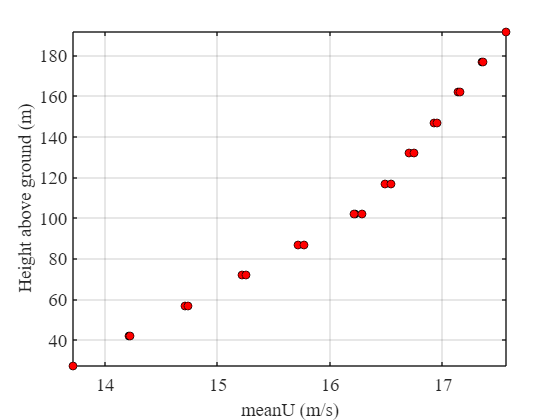


clf;close all;
figure
plot(reshape(mean(newU),[],1),nodes2.Z,'ko','markerfacecolor','r')
hold on
xlabel('meanU (m/s)')
ylabel('Height above ground (m)')
axis tight
set(findall(gcf,'-property','FontSize'),'FontSize',14,'FontName','Times')
set(gcf,'color','w')
grid on

## Check the Turbulence intensity simulated inside the grid

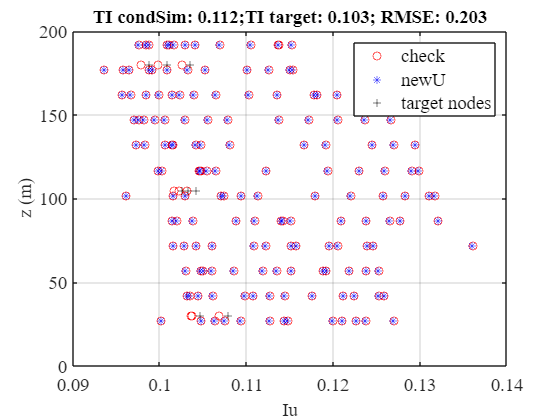

clf;close all;
figure
plot(std(uCheck)/mean(uCheck(:)),nodes2.Zcheck,'ro',...
    reshape(std(newU),[],Nyy*Nzz)/mean(newU(:)),nodes2.Z,'b*',...
    std(reshape(u0,[],9))./mean(u0(:)),nodes.Z(:),'k+')
legend('check','newU','target nodes')

newSTD = interp2(nodes.Y,nodes.Z,squeeze(std(u0)),newY,newZ);
myRMSE = RMSE(std(newU),newSTD(:)');


title(['TI condSim: ',num2str(mean(reshape(std(newU),[],Nyy*Nzz))./mean(u(:)),3),';TI target: ',...
    num2str(mean(std(reshape(u0,[],9))./mean(u(:))),3),'; RMSE: ',num2str(myRMSE,3)])
xlabel('Iu')
ylabel('z (m)')
set(findall(gcf,'-property','FontSize'),'FontSize',14,'FontName','Times')
set(gcf,'color','w')
grid on

## RMSE between target and simulated wind velocity at the nodes

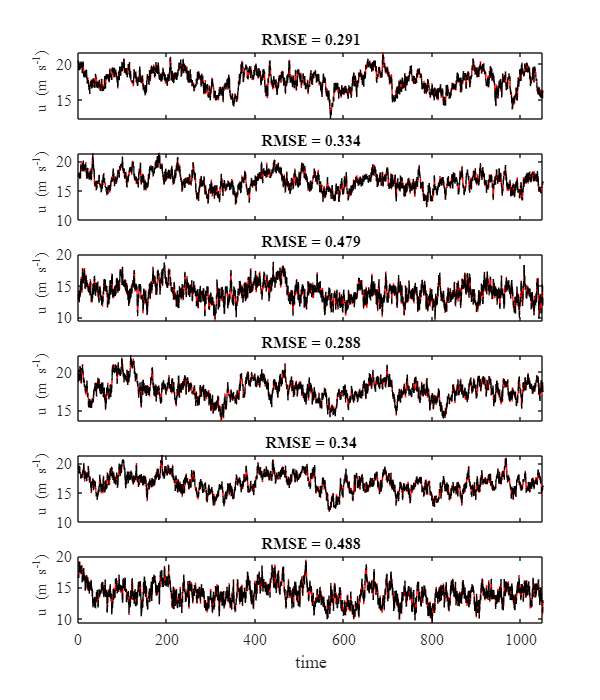

%  it should be near zero
clear ind2
clc
clf;close all

figure('position',[33    82   600   700])
tiledlayout(min(6,numel(y)),1,"TileSpacing","tight")
for jj=1:min(6,numel(y))
    nexttile
    [ind2] = find(nodes2.Ycheck(:)==y(jj) & nodes2.Zcheck(:)==z(jj));
    plot(t,uCheck(:,ind2),'r',t,u(jj,:),'k--');
    title(['RMSE = ',num2str(RMSE(uCheck(:,ind2),u(jj,:)),3)])
    xlim([0 1050])
    ylabel(' u (m s^{-1})')
    if jj<min(6,numel(y)),
        set(gca,'XTickLabel', []);
    end
end
set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')
set(gcf,'color','w')
xlabel('time')

## Check the PSD at the target and simulated nodes

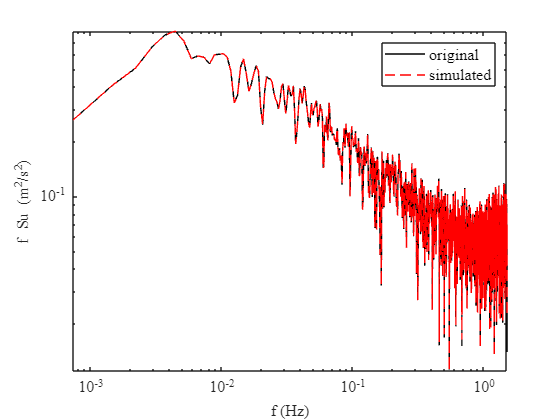

%  It should be identical
fs = 1/median(diff(t));
N = numel(t);
[ind2] = find(nodes2.Ycheck(:)==y(1) & nodes2.Zcheck(:)==z(1));

[Su0,f] = pwelch(detrend(u(1,:))',[],[],[],fs);
[Su1,f] = pwelch(detrend(uCheck(:,ind2))',[],[],[],fs);

figure
loglog(f,f.*Su0,'k',f,f.*Su1,'r--');
legend('original','simulated')
set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')
set(gcf,'color','w')
xlabel('f (Hz)')
ylabel ('f Su (m^2/s^2)')
axis tight
set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')

set(gcf,'color','w')

## Coherence

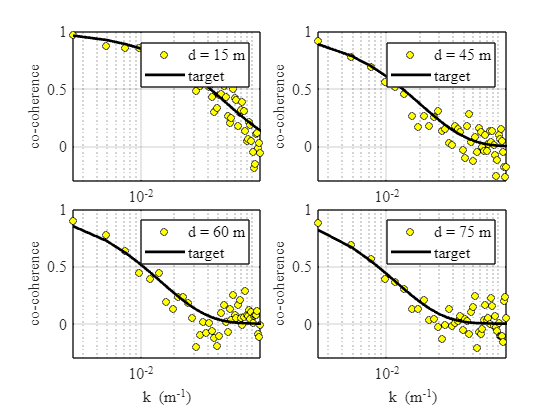

N = numel(t);
Nblock = 20; % a lot of block here to make it easier to visualize
Ncoh = round(N/Nblock);
if mod(Ncoh,2)
    cocoh = zeros(Nzz-1,round(Ncoh/2));
else
    cocoh = zeros(Nzz-1,round(Ncoh/2)+1);
end
% computation of the cocoherence using the function coherence
clear dy uCoh
ll=1;
for ii=2:Nzz
        [cocoh(ll,:),~,freq] = coherence(detrend(newU(:,2,1)),detrend(newU(:,2,ii)),Ncoh,round(Ncoh/2),Ncoh,fs);
        dy(ll) = abs(y1(2,ii)-y1(2,1));
        uCoh(ll) = 0.5* abs(mean(newU(:,2,1))+ mean(newU(:,2,ii)));
        ll=ll+1;
end

% matrix distance along y
distTarget = [20 40 60 80];
figure
tiledlayout(2,2,'TileSpacing','tight')
for ii=1:numel(distTarget)
    [~,indDist] = min(abs(dy-distTarget(ii)));
    k = 2*pi*freq./uCoh(indDist);
    nexttile
    semilogx(k,squeeze(cocoh(indDist,:)),'ko','markerfacecolor','y','markersize',5);
    box on;hold on
    plot(k,exp(-7.*dy(indDist).*freq/uCoh(indDist)),'k','linewidth',2);
    legend(['d = ',num2str(dy(indDist)),' m'],'target');
    xlim([0,0.12])
    ylim([-0.3,1])
    ylabel('co-coherence')
    if ii>2,        xlabel('k (m^{-1})');    end
    set(gcf,'color','w')
    grid on
end
set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')